**COMPUTE TRANSFER MATRICES FOR LINEAR MODELS**

**LONGITUDINAL RESPONSE**

clear
load linearMats.mat

Longitudinal channels:

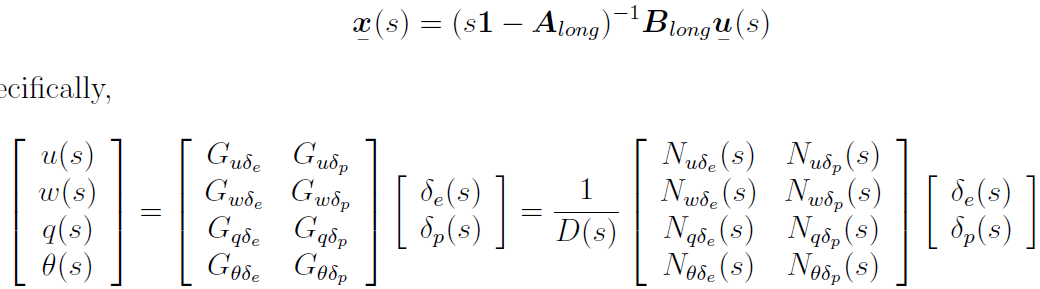

syms s
Xlong_s = inv(eye(4)*s - A_long)*B_long;

Lateral channels:

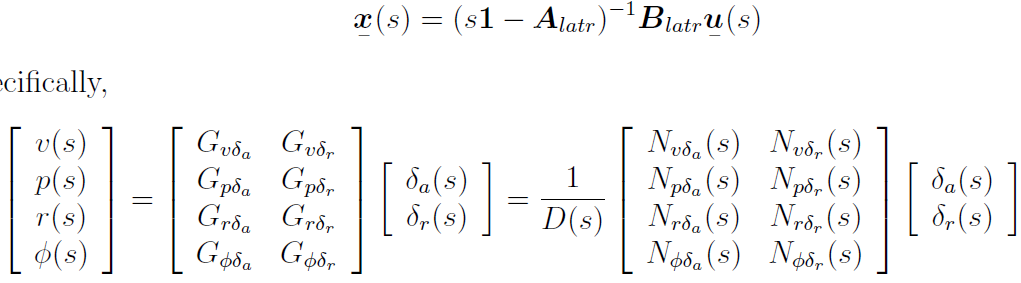

Xlatr_s = inv(eye(4)*s - A_latr)*B_latr;

Select specific channel TF for classical controller design:

% Example for response of pitch angle to elevator input
[G] = channelTF(Xlong_s(4,1))

G =
 
                -5.115e33 s^2 - 1.037e34 s - 3.733e32
  ------------------------------------------------------------------
  1.462e32 s^4 + 1.316e33 s^3 + 4.134e33 s^2 + 1.901e32 s + 1.205e32
 
Continuous-time transfer function.

